clear all;

% Initialize Pluto SDR Receiver and Transmitter
rx = sdrrx('Pluto');
tx = sdrtx('Pluto');

% Configure Receiver
rx.GainSource = 'AGC Fast Attack';
ch_size = 1e6; % Number of samples per frame
basebandSampleRate = 10e6; % Baseband sample rate
rx.SamplesPerFrame = ch_size; % Number of samples to process
rx.BasebandSampleRate = basebandSampleRate;

% Initialize Spectrum Analyzer
spectrumAnalyzer = spectrumAnalyzer('SampleRate', basebandSampleRate, ...
    'SpectrumType', 'Power density', ...
    'Title', 'Wireless Spectrum', ...
    'SpectralAverages', 20, ...
    'PlotMaxHoldTrace', true);

% Analyze 2.4 GHz Band
rx.CenterFrequency = 2.412e9; % Channel 1 of the 2.4 GHz band
disp('Analyzing 2.4 GHz Band...');

Analyzing 2.4 GHz Band...


for i = 1:10 % Collect and average multiple frames for better results
    data = rx(); % Receive data from SDR
    spectrumAnalyzer(data); % Plot spectrum
end

## Establishing connection to hardware. This process can take several seconds.


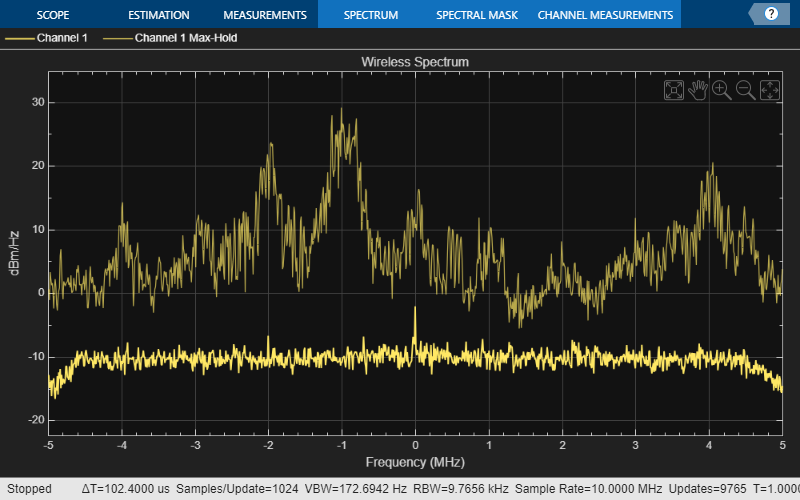


% Release resources
release(rx);
release(spectrumAnalyzer);

disp('Analysis complete. Spectrum plots saved as PNG.');

Analysis complete. Spectrum plots saved as PNG.
